Torque calculation for a minimum diameter of a shaft carrying 10kNm

clear all
clf

T_max = 10000; %Nm
d = 0.095; %m
tau_max = T_max / ((pi/16) * d^3) / 1e6

tau_max = 59.4018

for flydning

Sy = 370; %MPa
ny = 1.2; %Sikkerheds faktor
tau_till = 1/sqrt(3) * Sy / ny

tau_till = 178.0163

d_till = (T_max / ((pi/16) * (tau_till*1e6)))^(1/3)

d_till = 0.0659

How big should an claw area be to carry the force transfered

R = 0.1; %m afstand fra axel til claw
T_max = 10000;
% T = F*R
F= T_max/R

F = 100000


Sy = 370; %MPa
% S = F/A
A = F/Sy % mm^2

A = 270.2703


(30*10)

ans = 300

Normal force from rotation on a slinger for a slinger coupling

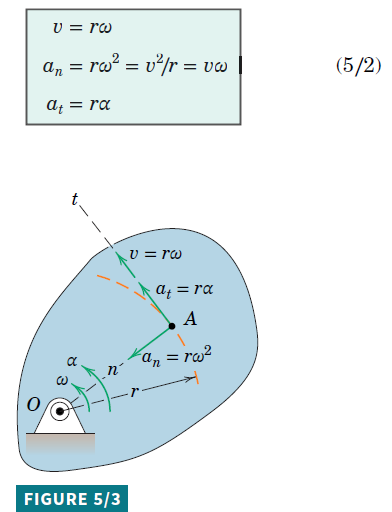$\omega = \frac{2 \cdot \pi}{60} \cdot n$ 

clear all
clf
format longg

m = 0.5; % kg % mass of the slinger part
R = 0.15; % meter from center to center of gravity
n = 3600; % rpm
mu_s = 0.2; % static friction coeffecient for steel on steel.
omega = 2 * pi / 60 * n % rad/s

omega =           376.991118430775



a_n = R * omega^2 % Normal acceleration

a_n =            21318.345506353



F_n = a_n * m

F_n =           10659.1727531765


Friction force

f_s = F_n * mu_s

f_s =            2131.8345506353




T_max = 10000; % torque
% T = F*R
F= T_max/R

F =           66666.6666666667


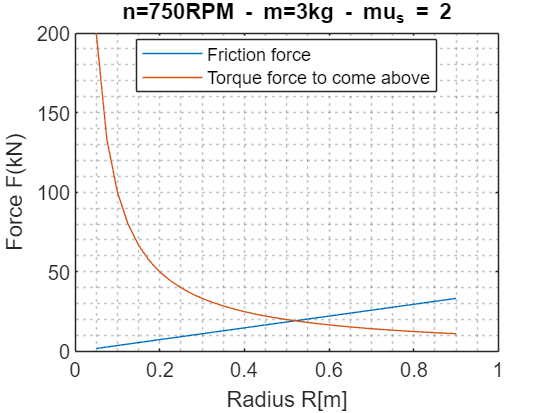

clear all
clf
format longg

m = 3.0; % kg % mass of the slinger part
R = 0.05:0.025:0.9; % meter from center to center of gravity
n = 750;%1800;%3600;%7200; % rpm
mu_s = 2.0; % static friction coeffecient for certain types of vulkanised rubbeer.
% https://roymech.org/Useful_Tables/Tribology/co_of_frict.html

omega = 2 * pi / 60 * n; % rad/s

a_n = R * omega^2; % Normal acceleration
F_n = a_n * m;
f_s = F_n * mu_s;


T_max = 10000;%1000 % torque
% T = F*R
F= T_max./R;
title_text = "n=" + string(n) + " RPM - m=" + string(m) + " kg - mu_s = " + mu_s;

plot(R,f_s/1000, DisplayName="Friction force")
hold on
title(title_text)
plot(R,F/1000, DisplayName="Torque force to come above")
xlabel("Radius R[m]")
ylabel("Force F(kN)")
grid("minor")
legend(Location='best')
hold off